## Practical math and computing workshop day 3

### Data I/O and Plotting

This exercise includes several mini projects. All of these requires reading in data, selecting a portion of the data to be plotted. Then plotting it in different ways.

Prerequisite: install wget via anaconda with something like: 

$ conda install -c anaconda wget

## Project 1. Download the excel sheet containing the historical weather station data from Atlanta GA from [https://o2.eas.gatech.edu/data/ATL_MonMeanTemp_1894_2020.xls](https://o2.eas.gatech.edu/data/ATL_MonMeanTemp_1894_2020.xls)

Select the mean Februrary temperature from 1900 to 2020 and make a line plot.[**¶**](http://localhost:8888/notebooks/Practical-Review-Math/class3_dataIO/Class3_dataIO_plot.ipynb#Select-the-mean-Februrary-temperature-from-1900-to-2020-and-make-a-line-plot.)

#### safety first

close all;
clear all;

#### Read in excel file using xlsread. 

Because the data is obtained from the web, I use wget command which is outside of MATLAB. If a line starts with !, shell command can be executed

! ~/opt/anaconda3/bin/wget https://o2.eas.gatech.edu/data/ATL_MonMeanTemp_1879_2020.xls

--2021-09-02 10:43:39--  https://o2.eas.gatech.edu/data/ATL_MonMeanTemp_1879_2020.xls
Resolving o2.eas.gatech.edu... 130.207.188.153
Connecting to o2.eas.gatech.edu|130.207.188.153|:443... connected.
HTTP request sent, awaiting response... 200 OK
Length: 48128 (47K) [application/vnd.ms-excel]
Saving to: 'ATL_MonMeanTemp_1879_2020.xls.2'


            ATL_MonMean   0%[                              ]       0  --.-KB/s               
ATL_MonMeanTemp_1879_20 100%[=============================>]  47.00K  --.-KB/s    in 0.02s   

2021-09-02 10:43:40 (2.57 MB/s) - 'ATL_MonMeanTemp_1879_2020.xls.2' saved [48128/48128]



data=xlsread('ATL_MonMeanTemp_1879_2020.xls');
data

data = 	1.0e+03 *

    1.8790    0.0443    0.0437    0.0576    0.0589    0.0698    0.0749    0.0796    0.0739    0.0687    0.0643    0.0539    0.0515
    1.8800    0.0543    0.0514    0.0555    0.0634    0.0710    0.0765    0.0792    0.0768    0.0694    0.0608    0.0472    0.0421
    1.8810    0.0401    0.0466    0.0491    0.0591    0.0708    0.0778    0.0811    0.0788    0.0755    0.0672    0.0526    0.0496
    1.8820    0.0488    0.0524    0.0574    0.0648    0.0661    0.0766    0.0759    0.0758    0.0717    0.0658    0.0511    0.0414
    1.8830    0.0430    0.0502    0.0502    0.0616    0.0674    0.0764    0.0801    0.0762    0.0713    0.0660    0.0537    0.0480
    1.8840    0.0359    0.0517    0.0544    0.0584    0.0707    0.0711    0.0777    0.0753    0.0749    0.0681    0.0513    0.0445
    1.8850    0.0400    0.0392    0.0472    0.0610    0.0669    0.0766    0.0788    0.0771    0.0701    0.0570    0.0506    0.0428
    1.8860    0.0362    0.0418    0.0509    0.0609    0.0685    

#### Extract Feb temperature 

atl=data;
year=atl(:,1);
feb=atl(:,3);

#### select the data range to be only within 1900 to 2020

index = (year >= 1900) & (year <= 2020);
year1 = year(index);
feb1  = feb(index);

#### plot the result

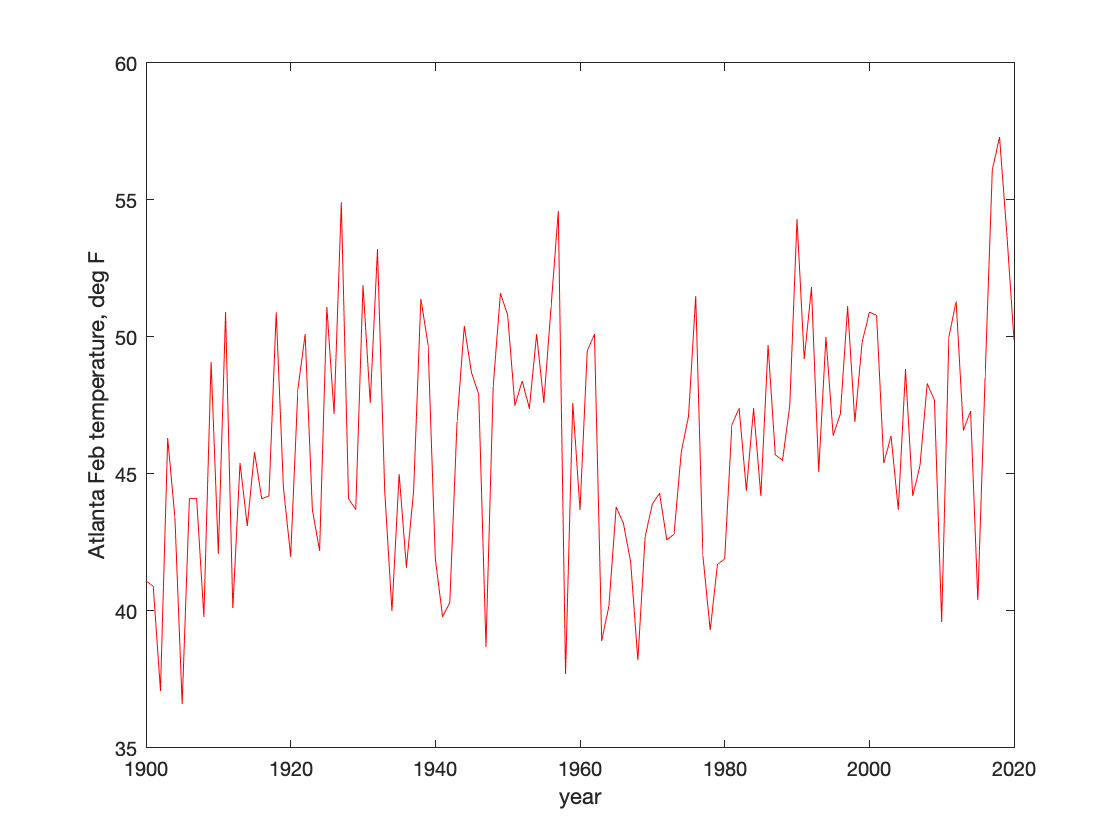

plot(year1,feb1,'r-');
xlabel('year');
ylabel('Atlanta Feb temperature, deg F');

## Project 2. Download the excel sheet containing the historical weather station data from Seattle WA from [https://o2.eas.gatech.edu/data/SEA_MonMeanTemp_1894_2020.xls](https://o2.eas.gatech.edu/data/SEA_MonMeanTemp_1894_2020.xls)

This data contains missing values as -999. Avoid plotting the missing data. Select the mean Februrary temperature from 1900 to 2020 and make a line plot.[**¶**](http://localhost:8888/notebooks/Practical-Review-Math/class3_dataIO/Class3_dataIO_plot.ipynb#This-data-contains-missing-values-as--999.-Avoid-plotting-the-missing-data.--Select-the-mean-Februrary-temperature-from-1900-to-2020-and-make-a-line-plot.)

#### use wget to get the data file. Then xlsread

! ~/opt/anaconda3/bin/wget https://o2.eas.gatech.edu/data/SEA_MonMeanTemp_1894_2020.xls

--2021-09-02 10:43:41--  https://o2.eas.gatech.edu/data/SEA_MonMeanTemp_1894_2020.xls
Resolving o2.eas.gatech.edu... 130.207.188.153
Connecting to o2.eas.gatech.edu|130.207.188.153|:443... connected.
HTTP request sent, awaiting response... 200 OK
Length: 42496 (42K) [application/vnd.ms-excel]
Saving to: 'SEA_MonMeanTemp_1894_2020.xls.1'


            SEA_MonMean   0%[                              ]       0  --.-KB/s               
SEA_MonMeanTemp_1894_20 100%[=============================>]  41.50K  --.-KB/s    in 0.02s   

2021-09-02 10:43:41 (2.65 MB/s) - 'SEA_MonMeanTemp_1894_2020.xls.1' saved [42496/42496]



data=xlsread('SEA_MonMeanTemp_1894_2020.xls');
data

data = 	1.0e+03 *

    1.8940    0.0388    0.0382    0.0427    0.0480    0.0534    0.0587    0.0643    0.0659    0.0576    0.0502    0.0474    0.0393
    1.8950    0.0387    0.0447    0.0441    0.0501    0.0552    0.0609    0.0636    0.0620    0.0558    0.0517    0.0442    0.0419
    1.8960    0.0424    0.0449    0.0427    0.0469    0.0524    0.0602    0.0672    0.0639    0.0567    0.0528    0.0384    0.0445
    1.8970    0.0400    0.0422    0.0402    0.0525    0.0584    0.0602    0.0627    0.0678    0.0569    0.0510    0.0436    0.0426
    1.8980    0.0399    0.0456    0.0434    0.0501    0.0571    0.0614    0.0646    0.0663    0.0608    0.0522    0.0450    0.0404
    1.8990    0.0417    0.0396    0.0434    0.0486    0.0515    0.0576    0.0650    0.0605    0.0610    0.0518    0.0519    0.0441
    1.9000    0.0438    0.0423    0.0500    0.0518    0.0560    0.0619    0.0650    0.0627    0.0586    0.0517    0.0443    0.0459
    1.9010    0.0402    0.0429    0.0460    0.0478    0.0554    

#### Extract Feb temperature

sea=data;
year_sea=sea(:,1);
feb_sea=sea(:,3);

**select the data range to be only within 1900 to 2020**

index = (year_sea >= 1900) & (year_sea <= 2020);
year2 = year_sea(index);
feb2  = feb_sea(index);

#### plot the result 

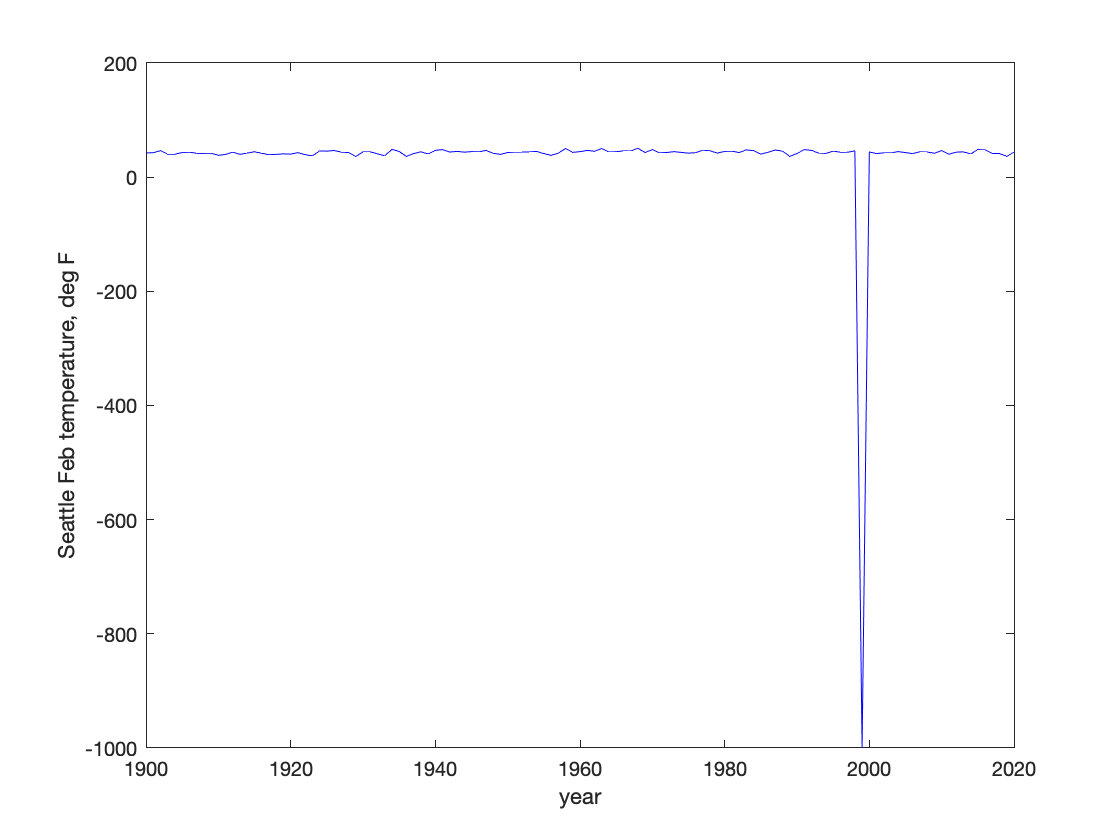

plot(year2,feb2,'b-');
xlabel('year');
ylabel('Seattle Feb temperature, deg F');

%% Oh no! the plot is ruined because there is a missing data (-999)

#### first replace the missing data (-999) with np.nan

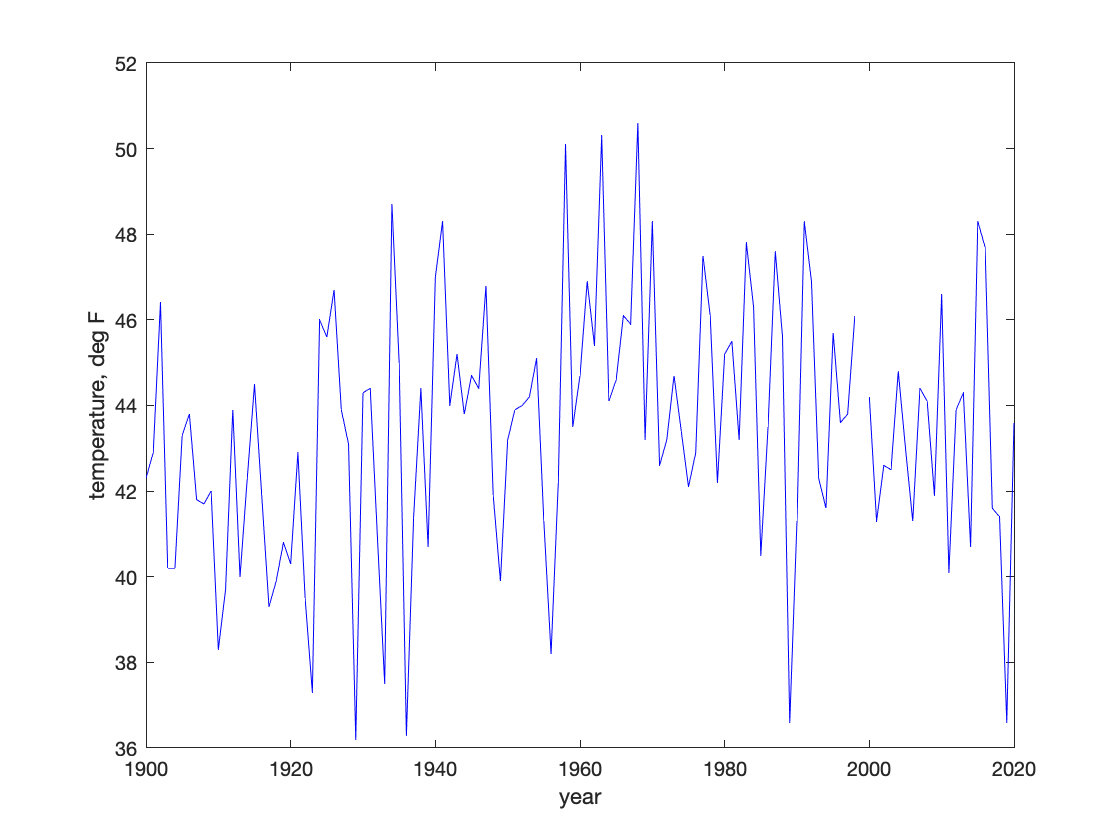

missing_index= (feb2 == -999); % first identify the missing data
feb2(missing_index)=NaN;

% then plot the result 
plot(year2,feb2,'b-');
xlabel('year');
ylabel('temperature, deg F');

% now we can see the stuff! 

## Project 3. Plot all 12 months of Atlanta data as a contour plot

use x-axis for year (1900-2020), y-axis for month (1-12), and color-filled contour for temperature.**Do the same for Seattle. You will have to remove the missing dataFor different choices of colormaps, please look at >>  help colormap**

% safety first
close all;
clear all;

% read in data file 
data=xlsread("ATL_MonMeanTemp_1879_2020.xls");

% Extract temperature for all 12 months
atl=data;
year=atl(:,1);     % first column
temp=atl(:,2:end);  % 2nd column and all the rest

% select the years from 1900 to 2020
index = (year >= 1900) & (year <= 2020);
year1 = year(index);
temp1 = temp(index,:);

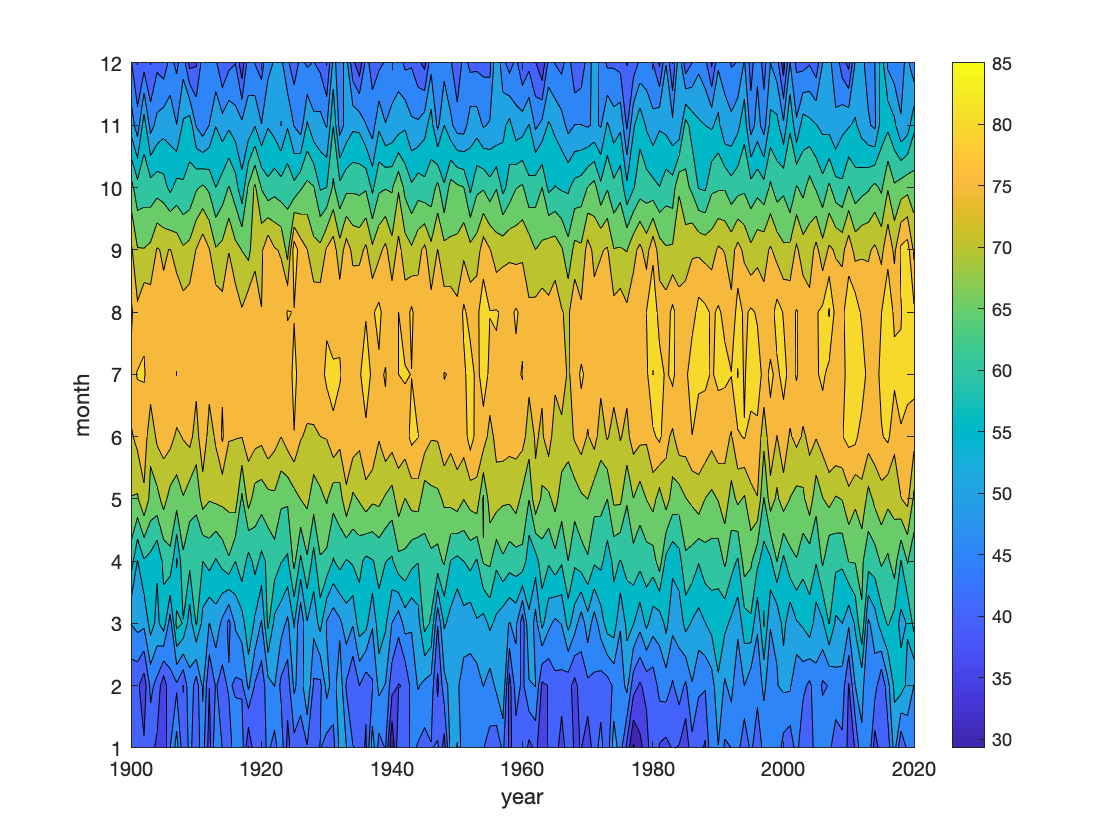

% contourf 
mon=1:12;
contourf(year1,mon,temp1'); % Try pcolor too
xlabel('year');
ylabel('month');
%colormap('jet')
colorbar;

% Let's try seattle now
data=xlsread("SEA_MonMeanTemp_1894_2020.xls");

% Extract temperature for all 12 months
sea=data;
year=sea(:,1);      % first column
temp=sea(:,2:end)   % 2nd column and all the rest

temp =    38.8000   38.2000   42.7000   48.0000   53.4000   58.7000   64.3000   65.9000   57.6000   50.2000   47.4000   39.3000
   38.7000   44.7000   44.1000   50.1000   55.2000   60.9000   63.6000   62.0000   55.8000   51.7000   44.2000   41.9000
   42.4000   44.9000   42.7000   46.9000   52.4000   60.2000   67.2000   63.9000   56.7000   52.8000   38.4000   44.5000
   40.0000   42.2000   40.2000   52.5000   58.4000   60.2000   62.7000   67.8000   56.9000   51.0000   43.6000   42.6000
   39.9000   45.6000   43.4000   50.1000   57.1000   61.4000   64.6000   66.3000   60.8000   52.2000   45.0000   40.4000
   41.7000   39.6000   43.4000   48.6000   51.5000   57.6000   65.0000   60.5000   61.0000   51.8000   51.9000   44.1000
   43.8000   42.3000   50.0000   51.8000   56.0000   61.9000   65.0000   62.7000   58.6000   51.7000   44.3000   45.9000
   40.2000   42.9000   46.0000   47.8000   55.4000   57.1000   61.7000   65.7000   58.0000   57.2000   49.1000   42.5000
   39.8000   46.4000   45


% select the years from 1900 to 2020
index = (year >= 1900) & (year <= 2020);
year2 = year(index);
temp2 = temp(index,:);

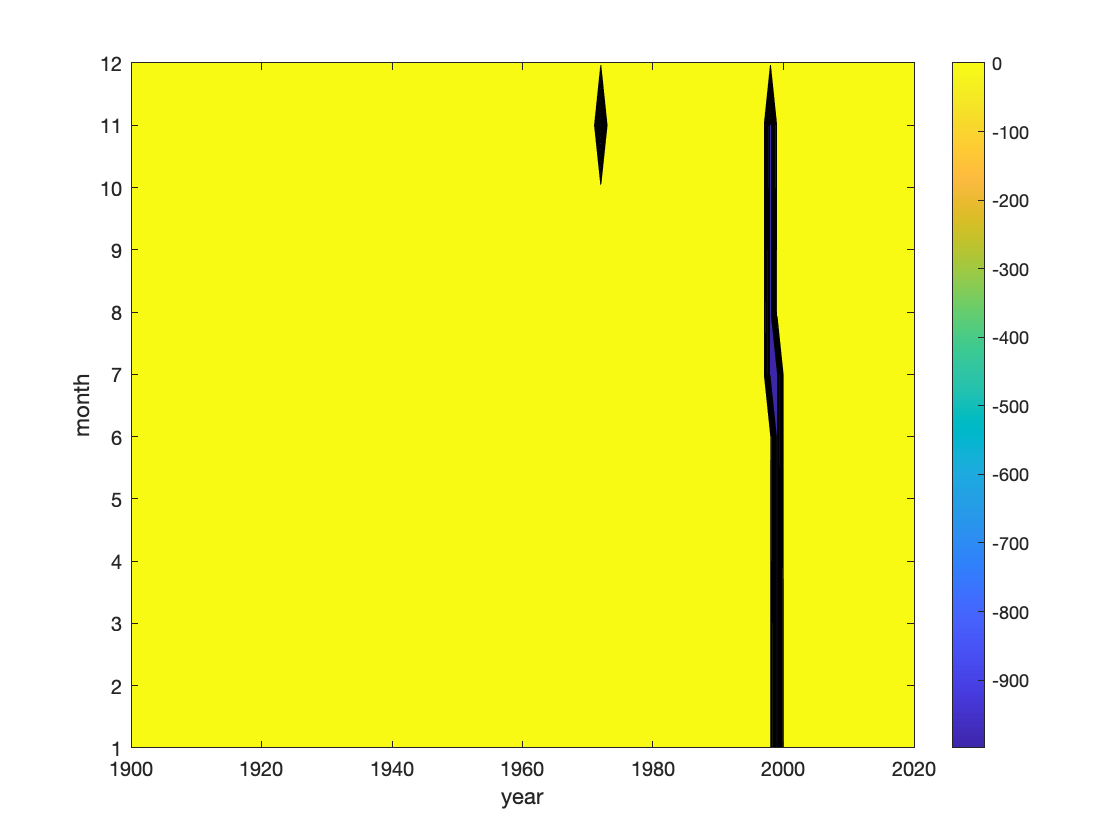

% contourf from matplotlib
contourf(year2,mon,temp2');
xlabel('year');
ylabel('month');
colorbar;

% Oh no! I fornot to replace the missing data (-999) again! 

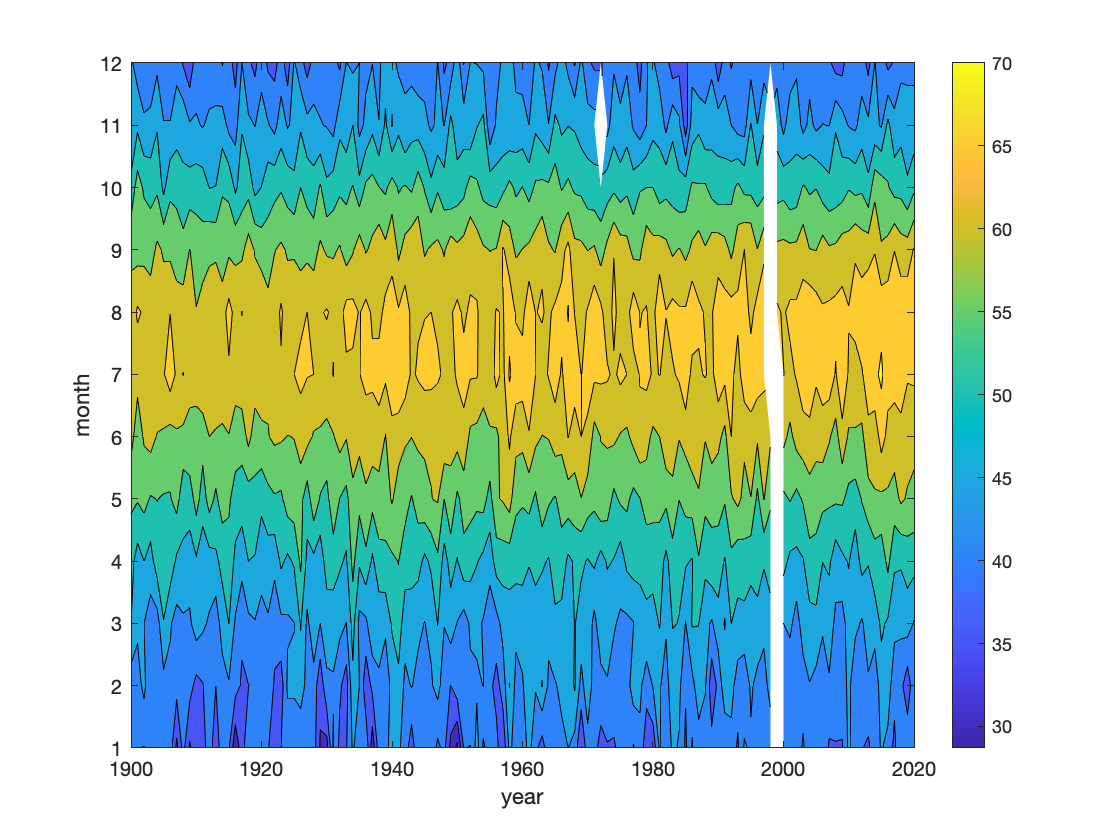

% replace missing data with np.nan
temp2(temp2 == -999) = NaN;  % directly insert the conditional statement as index

% contourf 
contourf(year2,mon,temp2');
xlabel('year');
ylabel('month');
colorbar;

% Yes! now I can see the data 
% empty spots are where the missing data is located

## Project 4. Display the monthly statistics using boxplot

Extract mean March data from Atlanta data. Select 1950 to 2020. Generate a box plot

% clear up the workspace
close all;
clear all;

% read in data file 
data=xlsread("ATL_MonMeanTemp_1879_2020.xls");

% Extract temperature 
atl=data;
year=atl(:,1);     % first column
mar=atl(:,4);  

% select the years from 1950 to 2020
index = (year >= 1950) & (year <= 2020);
year1 = year(index);
mar1 = mar(index,:);

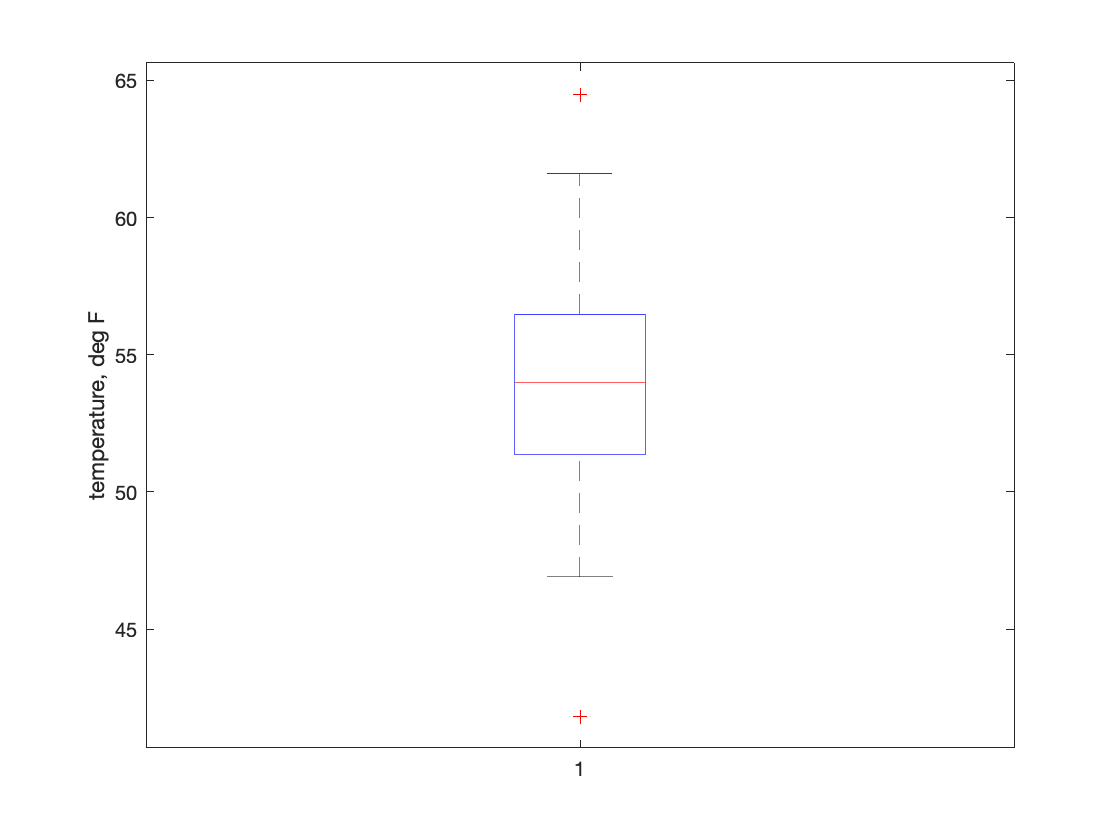

% generate a boxplot
boxplot(mar1);
ylabel('temperature, deg F');

**Extract all 12 months from the Atlanta data. Select 1950 to 2020. Generate a box plot for all 12 months and plot them side by side**

% Extract temperature for all 12 months
year=atl(:,1);       % first column
temp=atl(:,2:end);   % 2nd column and on

% select the years from 1950 to 2020
index = (year >= 1950) & (year <= 2020);
temp1 = temp(index,:);

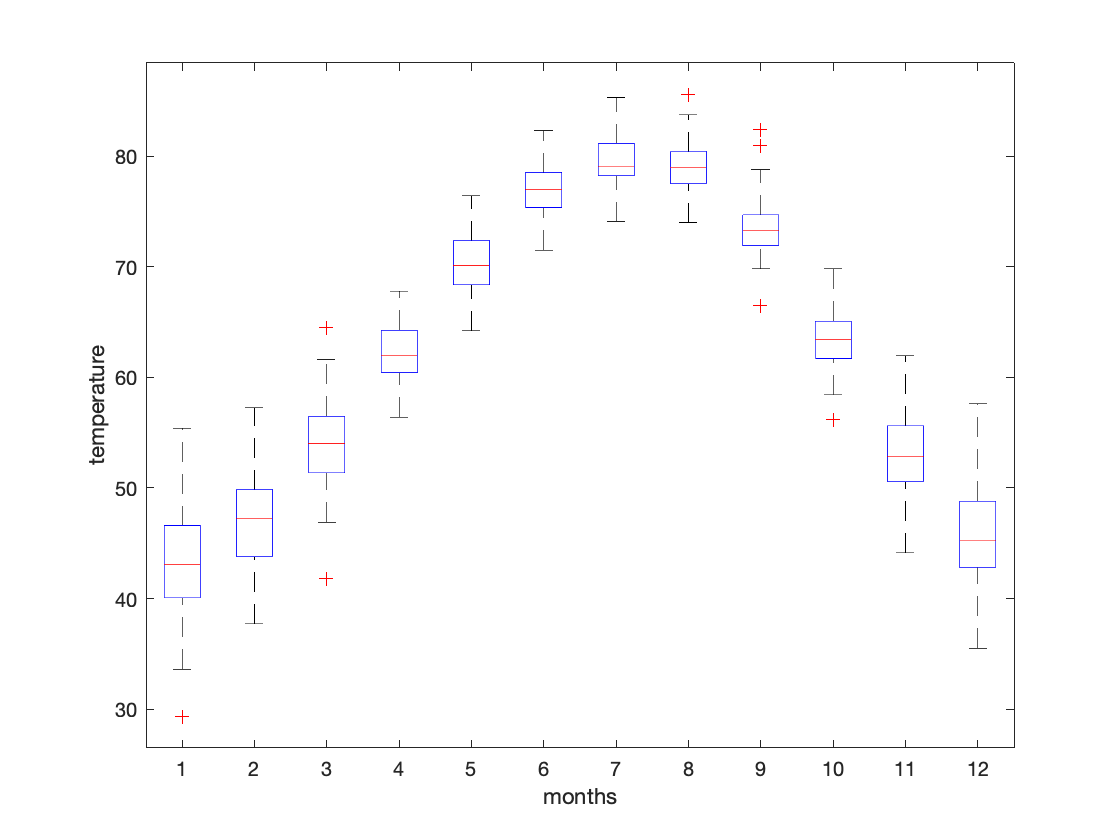

% plot boxplot all together
boxplot(temp1);
xlabel('months');
ylabel('temperature');

## Project 5. Display histogram

**Display the histogram of mean July temperature of Seattle from 1900 to 2020, and overlay Gaussian function**

Here, Gaussian f(x) is plotted scaled by N dx  

This is because the area of histogram is equal to sample size times bin width. 


$$$ f(x) = \frac{1}{\sqrt{2 \pi}\sigma} exp \left\{ -\frac{1}{2} \left( \frac{x-\mu}{\sigma} \right)^2\right\}$$$


% safety first
close all;
clear all;

data=xlsread("SEA_MonMeanTemp_1894_2020.xls");

% Extract temperature 
sea=data;
year=sea(:,1);      % first column
july=sea(:,8);   % 8th column 

% select the years from 1900 to 2020
index = (year >= 1900) & (year <= 2020);
year1 = year(index);
jul1 = july(index,:);

% remove the missing data as NaN
jul1( jul1 == -999)=NaN;

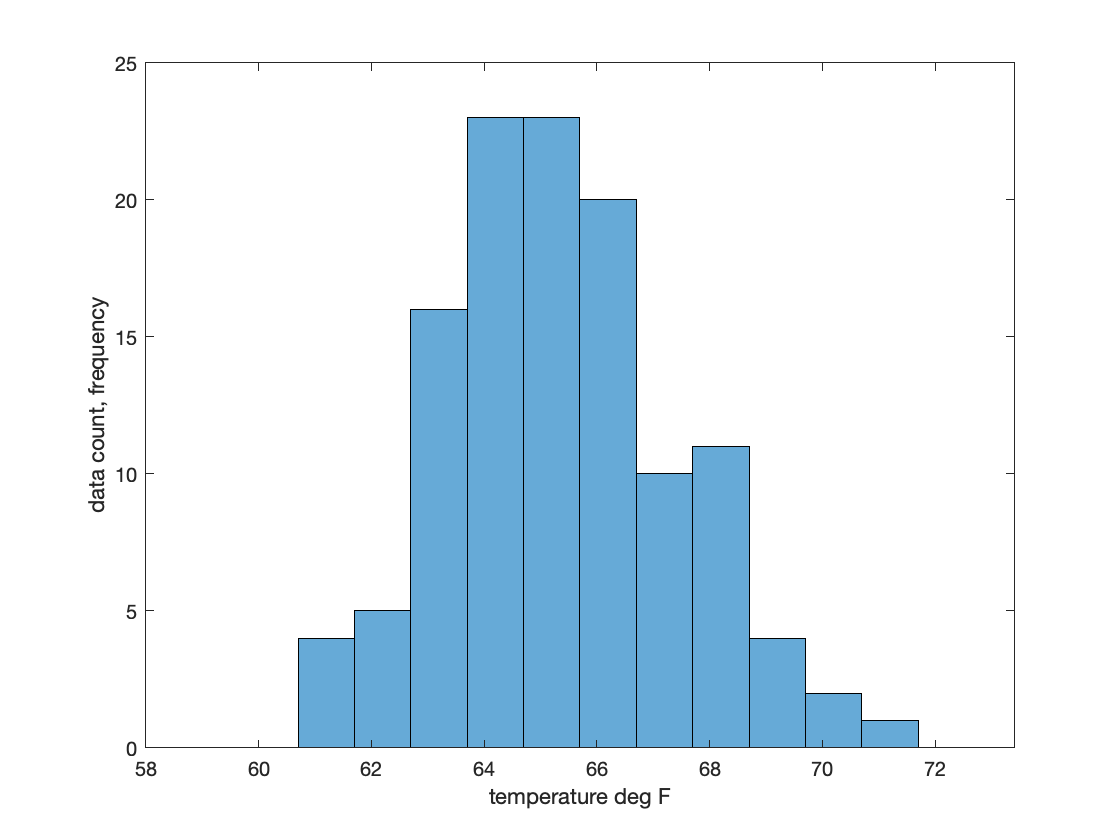

% define bins
dx=1;
bins=nanmin(jul1)-2:dx:nanmax(jul1)+2;
histogram(jul1,bins);
xlabel('temperature deg F');
ylabel('data count, frequency');

% calculate sample size
N=length(jul1);

% calculate mean and stdev
mu=nanmean(jul1);
sig=nanstd(jul1);

% calculate Gaussian overlay
x=nanmin(jul1)-2:0.1:nanmax(jul1)+2;
f=N*dx/(sqrt(2*pi)*sig)*exp(-.5*((x-mu)/sig).^2);

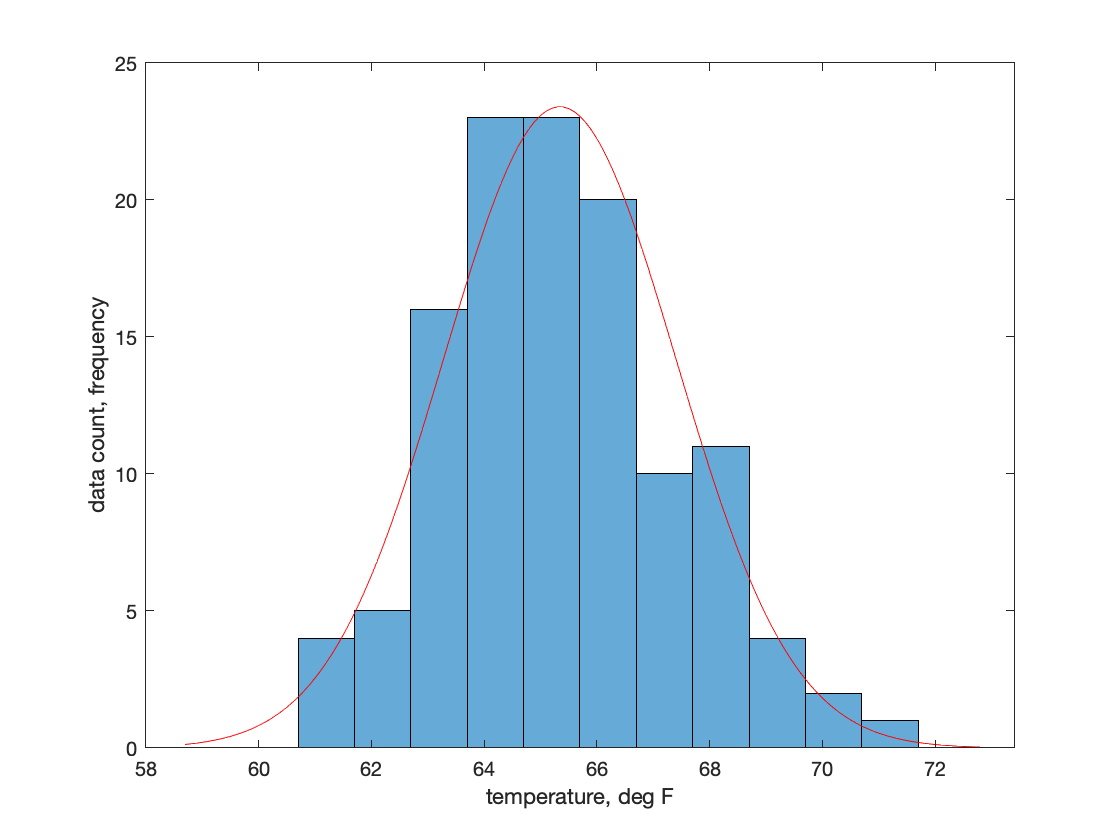

% replot the histogram
histogram(jul1,bins);
hold on;
plot(x,f,'r-');        %  plot the Gaussian
hold off;
xlabel('temperature, deg F');
ylabel('data count, frequency');

## Project 6. Create a scatter plot comparing January temperature of Atlanta and Seattle between 1900 and 2020

close all;
clear all;

% get Atlanta data
data=xlsread("ATL_MonMeanTemp_1879_2020.xls");

% Extract temperature 
atl=data;
year=atl(:,1);     % first column
jan=atl(:,2);  

% select the years from 1900 to 2020
index = (year >= 1900) & (year <= 2020);
year1 = year(index);
janatl = jan(index,:);

% get Seattle data 
data=xlsread("SEA_MonMeanTemp_1894_2020.xls");

% Extract temperature 
sea=data;
year=sea(:,1);      % first column
jan=sea(:,2);   % 2nd column 

% select the years from 1900 to 2020
index = (year >= 1900) & (year <= 2020);
year1 = year(index);
jansea = jan(index,:);

% remove the missing data as NaN
jansea( jansea == -999)=NaN;

**plot the scatter diagram**

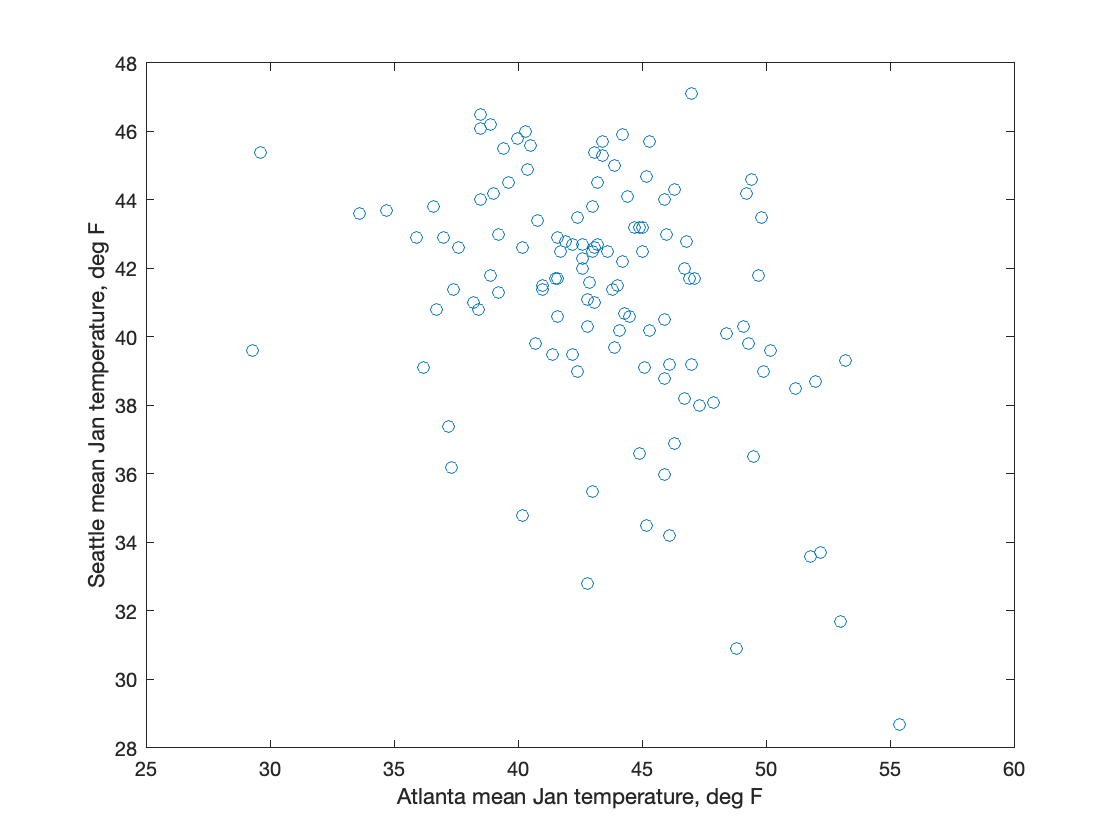

plot(janatl,jansea,'o')
xlabel('Atlanta mean Jan temperature, deg F')
ylabel('Seattle mean Jan temperature, deg F')

## Project 7. Save your result in a file

#### case 1. Save June, July, August months as a csv file

JJA=sea(:,[1 7 8 9]);
csvwrite("Seattle_JJA_1894_2020.csv",JJA);
JJA

JJA = 	1.0e+03 *

    1.8940    0.0587    0.0643    0.0659
    1.8950    0.0609    0.0636    0.0620
    1.8960    0.0602    0.0672    0.0639
    1.8970    0.0602    0.0627    0.0678
    1.8980    0.0614    0.0646    0.0663
    1.8990    0.0576    0.0650    0.0605
    1.9000    0.0619    0.0650    0.0627
    1.9010    0.0571    0.0617    0.0657
    1.9020    0.0606    0.0636    0.0644
    1.9030    0.0619    0.0619    0.0632


#### **case 2. save multiple arrays as .mat file**

save ATL_SEA.mat sea atl;
% to read in, load filename.mat;